Vaja 3

clear all; clc

Nalaganje podatkov v matlab

nir = dir(['oseba*.nir']);
ldf = dir(['oseba*.ldf']);
po2 = dir(['oseba*.po2']);

for ii=1:6
    os(ii).nir=load(nir(ii).name);
    os(ii).ldf=load(ldf(ii).name);
    os(ii).po2=load(po2(ii).name);
end

Grafi

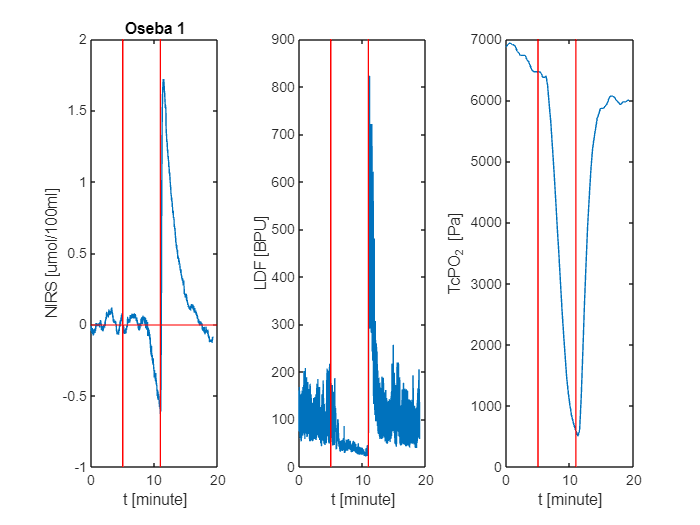

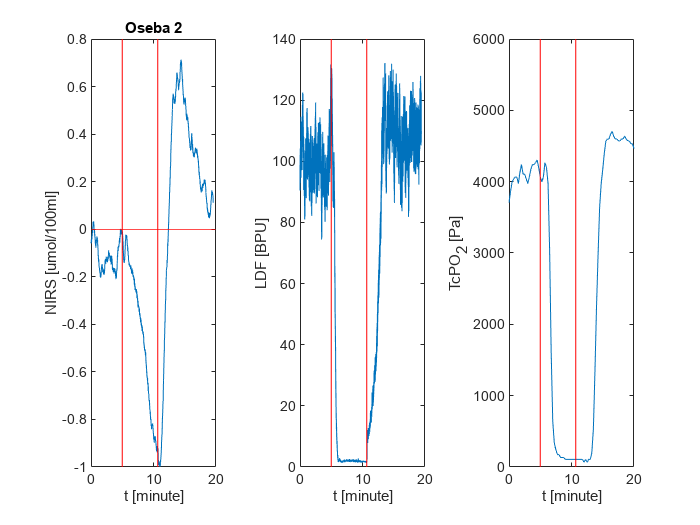

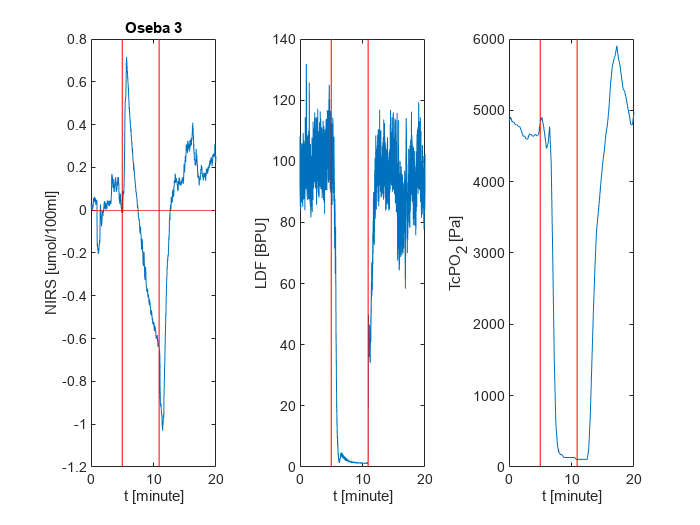

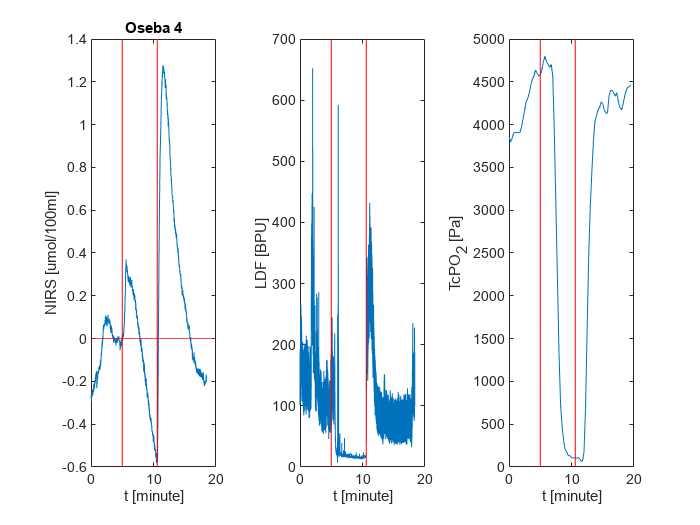

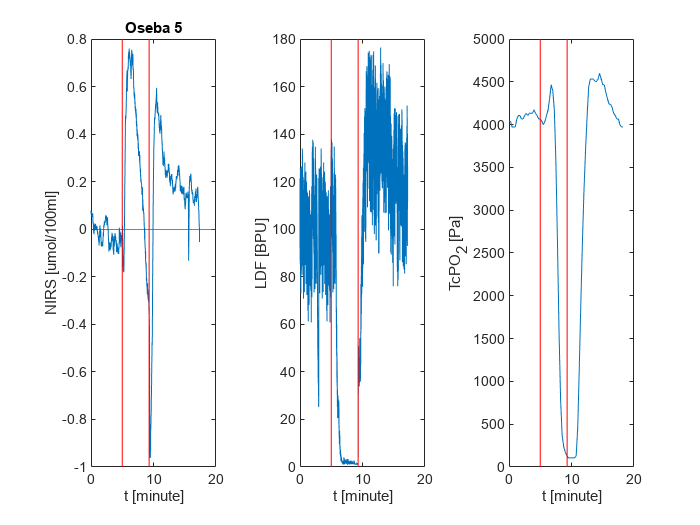

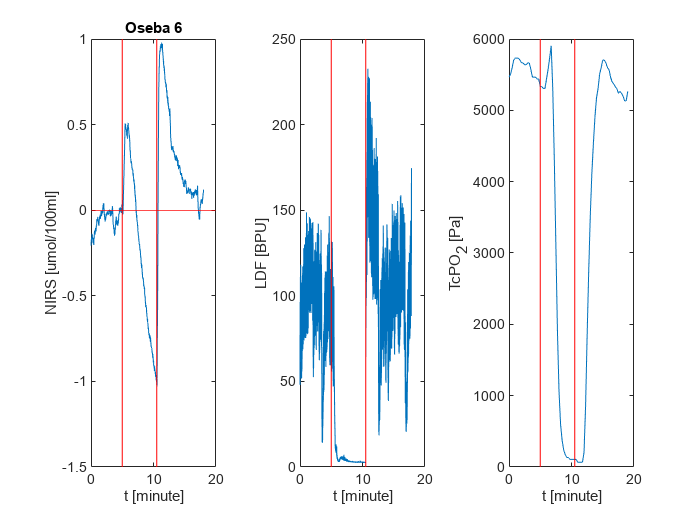

for ii = 1:6
    i_1(ii) = find(os(ii).ldf(:,3) == 1, 1, 'first'); 
    j_1(ii) = find(os(ii).ldf(:,3) == 2, 1, 'first');
    os(ii).po2(:,2)=os(ii).po2(:,2)*133.3;
    
    naslov = ['Oseba ' num2str(ii)];
    
    figure;
    tiledlayout(1, 3);
    nexttile;
    plot(os(ii).nir(:,1), os(ii).nir(:,2)); 
    xlabel('t [minute]'); 
    ylabel('NIRS [umol/100ml]');
    title(naslov)
    line([os(ii).ldf(i_1(ii)) os(ii).ldf(i_1(ii))], ylim, 'color', 'r');
    line([os(ii).ldf(j_1(ii)) os(ii).ldf(j_1(ii))], ylim, 'color', 'r');
    yline(0,'color', 'r');
    h = axis;
    axis([0,20,h(3),h(4)])
    
    nexttile; 
    plot(os(ii).ldf(:,1), os(ii).ldf(:,2)); 
    xlabel('t [minute]');
    ylabel('LDF [BPU]');
    line([os(ii).ldf(i_1(ii)) os(ii).ldf(i_1(ii))], ylim, 'color', 'r');
    line([os(ii).ldf(j_1(ii)) os(ii).ldf(j_1(ii))], ylim, 'color', 'r');
    h = axis;
    axis([0,20,h(3),h(4)])
    
    nexttile; 
    plot(os(ii).po2(:,1), os(ii).po2(:,2)); 
    xlabel('t [minute]'); 
    ylabel('TcPO_2 [Pa]');
    line([os(ii).ldf(i_1(ii)) os(ii).ldf(i_1(ii))], ylim, 'color', 'r');
    line([os(ii).ldf(j_1(ii)) os(ii).ldf(j_1(ii))], ylim, 'color', 'r');
    h = axis;
    axis([0,20,h(3),h(4)])
    
end

Izračun MR

for ii=1:6
    minimum = min(os.ldf(:,2))